# Impedance Control Test

clear all
close all
clc

## Implementation Plan:

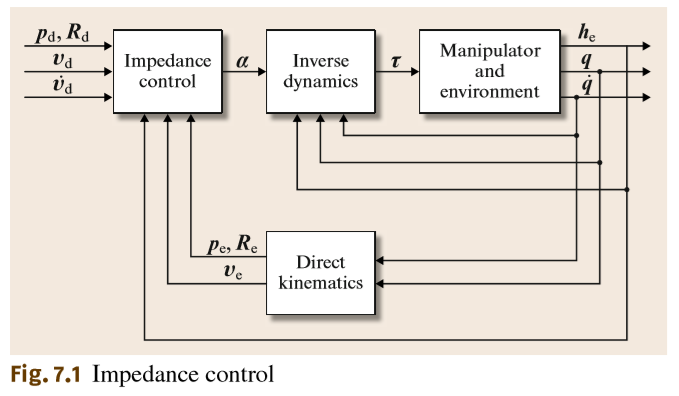

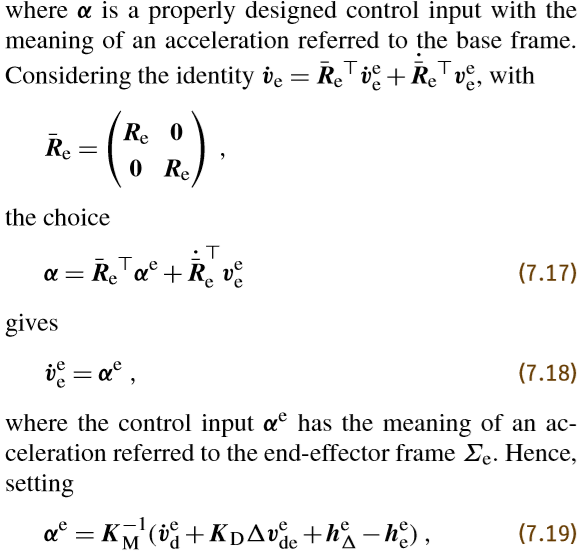

**Testing the Skew Symmetric Matrix**

syms theta
R = rotx(theta)

$$R = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\theta \right) & -\sin\left(\theta \right)\\ 0 & \sin\left(\theta \right) & \cos\left(\theta \right) \end{array}\right)$$

Rd = diff(R,theta)

$$Rd = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & -\sin\left(\theta \right) & -\cos\left(\theta \right)\\ 0 & \cos\left(\theta \right) & -\sin\left(\theta \right) \end{array}\right)$$

S = simplify(Rd*R')

$$S = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & -\sin\left(\theta -\bar{\theta }\right) & -\cos\left(\theta -\bar{\theta }\right)\\ 0 & \cos\left(\theta -\bar{\theta }\right) & -\sin\left(\theta -\bar{\theta }\right) \end{array}\right)$$

Rdiff = simplify(S*R)

$$Rdiff = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & -\sin\left(2\,\theta -\bar{\theta }\right) & -\cos\left(2\,\theta -\bar{\theta }\right)\\ 0 & \cos\left(2\,\theta -\bar{\theta }\right) & -\sin\left(2\,\theta -\bar{\theta }\right) \end{array}\right)$$

disp('Testing with 0 rad')

Testing with 0 rad


subs(Rdiff,theta,0)

$$ans = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & -1\\ 0 & 1 & 0 \end{array}\right)$$

**The actual formula.**

disp('Genearl Theory')

Genearl Theory


syms ax ay az
Skew = [0 -az ay; az 0 -ax; -ay ax 0]

$$Skew = \left(\begin{array}{ccc} 0 & -\mathrm{az} & \mathrm{ay}\\ \mathrm{az} & 0 & -\mathrm{ax}\\ -\mathrm{ay} & \mathrm{ax} & 0 \end{array}\right)$$

SkM = subs(Skew,[ax,ay,az], [1,0,0])

$$SkM = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & -1\\ 0 & 1 & 0 \end{array}\right)$$

% Formulating equations:
syms kpt theta 

K_Pt = eye(3)*kpt;
Rd = rotx(theta)

$$Rd = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\theta \right) & -\sin\left(\theta \right)\\ 0 & \sin\left(\theta \right) & \cos\left(\theta \right) \end{array}\right)$$

Re = rotx(theta)

$$Re = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\theta \right) & -\sin\left(\theta \right)\\ 0 & \sin\left(\theta \right) & \cos\left(\theta \right) \end{array}\right)$$

syms p_dx p_ex p_dy p_ey p_dz p_ez
% syms set, but for reference:
% delta_p_de = pd - pe

p_d = [p_dx;p_dy;p_dz];
p_e = [p_ex;p_ey;p_ez];

delta_p_de = p_d - p_e

$$delta\_p\_de = \left(\begin{array}{c} p_{\mathrm{dx}}-p_{\mathrm{ex}}\\ p_{\mathrm{dy}}-p_{\mathrm{ey}}\\ p_{\mathrm{dz}}-p_{\mathrm{ez}} \end{array}\right)$$

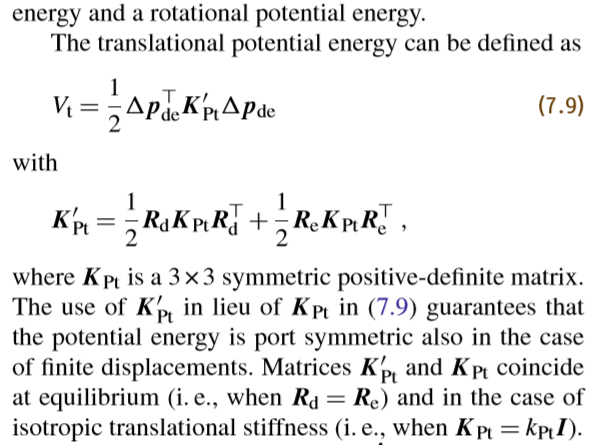


K_prime_Pt = (1/2) * Rd * K_Pt * Rd' + (1/2)*Re * K_Pt * Re';
K_prime_Pt = simplify(K_prime_Pt)

$$K\_prime\_Pt = \left(\begin{array}{ccc} \mathrm{kpt} & 0 & 0\\ 0 & \mathrm{kpt}\,\cos\left(\theta -\bar{\theta }\right) & -\mathrm{kpt}\,\sin\left(\theta -\bar{\theta }\right)\\ 0 & \mathrm{kpt}\,\sin\left(\theta -\bar{\theta }\right) & \mathrm{kpt}\,\cos\left(\theta -\bar{\theta }\right) \end{array}\right)$$

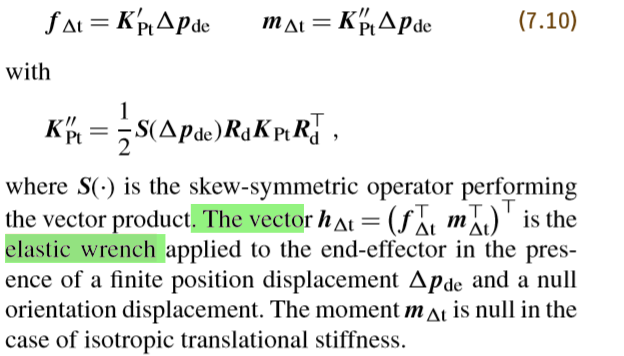


% vec = [1;0;0];
S = skewvec3D(delta_p_de);

K_pprime_Pt = (1/2)* Skew * Rd * K_Pt * Rd';
K_pprime_Pt = simplify(K_pprime_Pt)

$$K\_pprime\_Pt = \begin{array}{l} \left(\begin{array}{ccc} 0 & -\mathrm{kpt}\,\cos\left(\bar{\theta }\right)\,\sigma_{1}-\mathrm{kpt}\,\sin\left(\bar{\theta }\right)\,\sigma_{2} & \mathrm{kpt}\,\cos\left(\bar{\theta }\right)\,\sigma_{2}-\mathrm{kpt}\,\sin\left(\bar{\theta }\right)\,\sigma_{1}\\ \frac{\mathrm{az}\,\mathrm{kpt}}{2} & \sigma_{3} & -\sigma_{4}\\ -\frac{\mathrm{ay}\,\mathrm{kpt}}{2} & \sigma_{4} & \sigma_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\mathrm{az}\,\cos\left(\theta \right)}{2}-\frac{\mathrm{ay}\,\sin\left(\theta \right)}{2}\\ \sigma_{2}=\frac{\mathrm{ay}\,\cos\left(\theta \right)}{2}+\frac{\mathrm{az}\,\sin\left(\theta \right)}{2}\\ \sigma_{3}=-\frac{\mathrm{ax}\,\mathrm{kpt}\,\sin\left(\theta -\bar{\theta }\right)}{2}\\ \sigma_{4}=\frac{\mathrm{ax}\,\mathrm{kpt}\,\cos\left(\theta -\bar{\theta }\right)}{2} \end{array}$$

 
f_delta_t = K_prime_Pt * delta_p_de;
f_delta_t = simplify(f_delta_t)

$$f\_delta\_t = \left(\begin{array}{c} \mathrm{kpt}\,\left(p_{\mathrm{dx}}-p_{\mathrm{ex}}\right)\\ \mathrm{kpt}\,\cos\left(\theta -\bar{\theta }\right)\,\left(p_{\mathrm{dy}}-p_{\mathrm{ey}}\right)-\mathrm{kpt}\,\sin\left(\theta -\bar{\theta }\right)\,\left(p_{\mathrm{dz}}-p_{\mathrm{ez}}\right)\\ \mathrm{kpt}\,\cos\left(\theta -\bar{\theta }\right)\,\left(p_{\mathrm{dz}}-p_{\mathrm{ez}}\right)+\mathrm{kpt}\,\sin\left(\theta -\bar{\theta }\right)\,\left(p_{\mathrm{dy}}-p_{\mathrm{ey}}\right) \end{array}\right)$$



m_delta_t = K_pprime_Pt * delta_p_de ;
m_delta_t = simplify(m_delta_t)

$$m\_delta\_t = \begin{array}{l} \left(\begin{array}{c} \left(p_{\mathrm{dz}}-p_{\mathrm{ez}}\right)\,\left(\mathrm{kpt}\,\cos\left(\bar{\theta }\right)\,\sigma_{2}-\mathrm{kpt}\,\sin\left(\bar{\theta }\right)\,\sigma_{1}\right)-\left(p_{\mathrm{dy}}-p_{\mathrm{ey}}\right)\,\left(\mathrm{kpt}\,\cos\left(\bar{\theta }\right)\,\sigma_{1}+\mathrm{kpt}\,\sin\left(\bar{\theta }\right)\,\sigma_{2}\right)\\ \frac{\mathrm{az}\,\mathrm{kpt}\,\left(p_{\mathrm{dx}}-p_{\mathrm{ex}}\right)}{2}-\frac{\mathrm{ax}\,\mathrm{kpt}\,\sigma_{4}\,\left(p_{\mathrm{dz}}-p_{\mathrm{ez}}\right)}{2}-\frac{\mathrm{ax}\,\mathrm{kpt}\,\sigma_{3}\,\left(p_{\mathrm{dy}}-p_{\mathrm{ey}}\right)}{2}\\ \frac{\mathrm{ax}\,\mathrm{kpt}\,\sigma_{4}\,\left(p_{\mathrm{dy}}-p_{\mathrm{ey}}\right)}{2}-\frac{\mathrm{ay}\,\mathrm{kpt}\,\left(p_{\mathrm{dx}}-p_{\mathrm{ex}}\right)}{2}-\frac{\mathrm{ax}\,\mathrm{kpt}\,\sigma_{3}\,\left(p_{\mathrm{dz}}-p_{\mathrm{ez}}\right)}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\mathrm{az}\,\cos\left(\theta \right)}{2}-\frac{\mathrm{ay}\,\sin\left(\theta \right)}{2}\\ \sigma_{2}=\frac{\mathrm{ay}\,\cos\left(\theta \right)}{2}+\frac{\mathrm{az}\,\sin\left(\theta \right)}{2}\\ \sigma_{3}=\sin\left(\theta -\bar{\theta }\right)\\ \sigma_{4}=\cos\left(\theta -\bar{\theta }\right) \end{array}$$

**Further more**

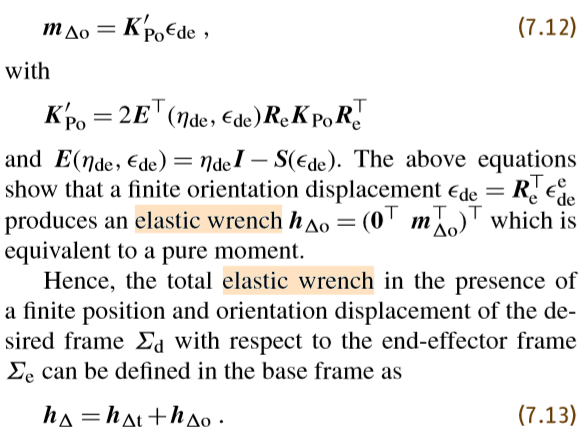

-------------------

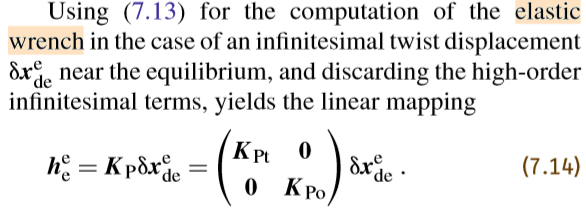

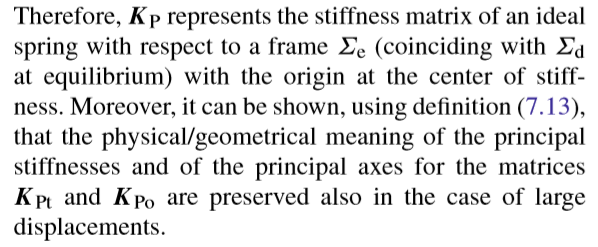

--------------------

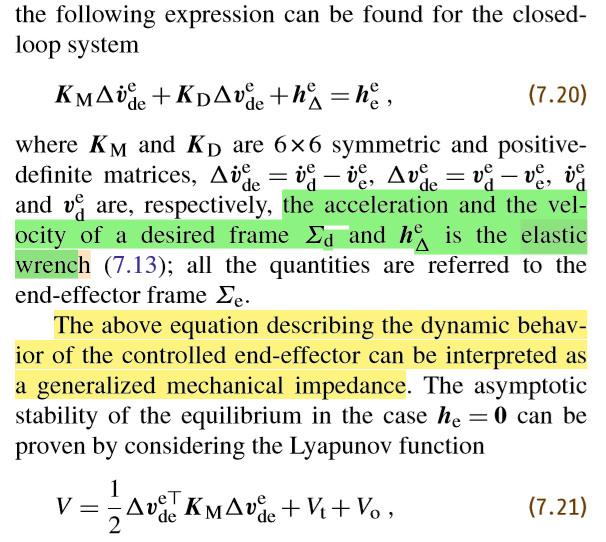

## Implementing equations:


% Re = rotx(theta)
% Rbar = [Re zeros(3,3); zeros(3,3) Re]
% 
% delta_vde_e = (vd_e - ve_e)
% d_delta_vde_e = (vd_e - ve_e)
% 
% alpha_e = inv(KM) * (vd_e_dot + KD*delta_vde_e)
% alpha = Rbar' * alpha_e * Rbar_d' *ve_e

testing

% syms Md Bd Kd

Md = 5

Md = 5

Kd = 1

Kd = 1

Bd = 1

Bd = 1


s = zpk('s')


s =
 
  s
 
Continuous-time zero/pole/gain model.



num = [1]

num = 1

den = [Md Bd Kd]

den =      5     1     1


sys = tf(num,den)


sys =
 
        1
  -------------
  5 s^2 + s + 1
 
Continuous-time transfer function.




[wn,zeta] = damp(sys)

wn =     0.4472
    0.4472


zeta =     0.2236
    0.2236


syms omega_n s zeta


sys = (omega_n^2) / (s^2 + 2*zeta*omega_n*s + omega_n^2)

$$sys = \frac{{\omega_{n}}^{2}}{{\omega_{n}}^{2}+2\,\zeta \,\omega_{n}\,s+s^{2}}$$


sys = subs(sys,zeta,1)

$$sys = \frac{{\omega_{n}}^{2}}{{\omega_{n}}^{2}+2\,\omega_{n}\,s+s^{2}}$$

solve(sys)

 
ans =
 
Empty sym: 0-by-1
 


syms q1(t) q2(t)

alpha =[0 0];
d = [0 0];
theta = [q1(t) q2(t)];
a = [0.7 0.7];
collect = [];
T = eye(4);

for i = 1:2
    collect{i} = [cos(theta(i)) -cos(alpha(i))*sin(theta(i)) sin(alpha(i))*sin(theta(i)) a(i)*cos(theta(i));
        sin(theta(i)) cos(alpha(i))*cos(theta(i)) -sin(alpha(i))*cos(theta(i)) a(i)*sin(theta(i));
        0 sin(alpha(i)) cos(alpha(i)) d(i);
        0 0 0 1];   
    T = T* collect{i};
end
A1 = collect{1};
A2 = collect{2};

% syms l1 l2
% A1c = subs(A1, [a1,a2],[l1,l2]);

% R1 = A1(1:3,1:3);
% R2 = A2(1:3,1:3);


J1 = [cross([0 0 1]',T(1:3,4)); [0 0 1]'];
J2 = [cross(A1(1:3,3),T(1:3,4)-A1(1:3,4)) ; A1(1:3,3)];
J = [J1 J2];
Jd = simplify(diff(J,t))

$$Jd = \begin{array}{l} \left(\begin{array}{cc} -\frac{7\,\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{10}-\frac{7\,\cos\left(\sigma_{2}\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{10}-\frac{7\,\cos\left(\sigma_{2}\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)}{10} & -\frac{7\,\cos\left(\sigma_{2}\right)\,\sigma_{1}}{10}\\ -\frac{7\,\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{10}-\frac{7\,\sin\left(\sigma_{2}\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{10}-\frac{7\,\sin\left(\sigma_{2}\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)}{10} & -\frac{7\,\sin\left(\sigma_{2}\right)\,\sigma_{1}}{10}\\ 0 & 0\\ 0 & 0\\ 0 & 0\\ 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial }{\partial t}q_{1}\left(t\right)+\frac{\partial }{\partial t}q_{2}\left(t\right)\\ \sigma_{2}=q_{1}\left(t\right)+q_{2}\left(t\right) \end{array}$$

syms q1d q2d q1c q2c
Jd = subs(Jd,[q1(t), q2(t), diff(q1(t),t),diff(q2(t),t)],[q1c,q2c,q1d,q2d]);
Jd = Jd'

$$Jd = \begin{array}{l} \left(\begin{array}{cccccc} -\frac{7\,\cos\left(\bar{\mathrm{q1c}}\right)\,\bar{\mathrm{q1d}}}{10}-\frac{7\,\sigma_{2}\,\bar{\mathrm{q1d}}}{10}-\frac{7\,\sigma_{2}\,\bar{\mathrm{q2d}}}{10} & -\frac{7\,\sin\left(\bar{\mathrm{q1c}}\right)\,\bar{\mathrm{q1d}}}{10}-\frac{7\,\sigma_{1}\,\bar{\mathrm{q1d}}}{10}-\frac{7\,\sigma_{1}\,\bar{\mathrm{q2d}}}{10} & 0 & 0 & 0 & 0\\ -\frac{7\,\sigma_{2}\,\left(\bar{\mathrm{q1d}}+\bar{\mathrm{q2d}}\right)}{10} & -\frac{7\,\sigma_{1}\,\left(\bar{\mathrm{q1d}}+\bar{\mathrm{q2d}}\right)}{10} & 0 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\bar{\mathrm{q1c}}+\bar{\mathrm{q2c}}\right)\\ \sigma_{2}=\cos\left(\bar{\mathrm{q1c}}+\bar{\mathrm{q2c}}\right) \end{array}$$

## Functions

function S = skewvec3D(vec)
    syms ax ay az    
    v = [];
    
    for i = 1:length(vec)
       v = [v vec(i)];
    end
    
    Skew = [0 -az ay; az 0 -ax; -ay ax 0];
    S = subs(Skew,[ax,ay,az], v);
end